# Sensobed, review del código y proyecto

## Dudas:

- Muestreo: Se toma una frecuencia de muestreo de 200, mientras que en el informe indica 500Hz. Promedio,  ¿64 o 128?

- Filtros: Vemos que falta el filtro FPB de 0,5Hz (además no encontramos el sentido de este filtro). Obviando el último FPB, las frecuencias de corte de los filtros no coinciden con las del PDF (ver gráficas abajo).

- No sabemos por qué cuando muestra_h<100, actividad = 1.

- ¿Por qué el procesado se hace en serie y no en paralelo a la toma de muestras? En el pulso.

- ¿En el pulso cardíaco, por qué se eleva al cuadrado la muestra después de filtrar la primera vez?

- Puede haber casos en los que no se respeta la frecuencia de muestreo.

- Estabilidad del algoritmo para la respiración.

Cosas interesantes:

-   

   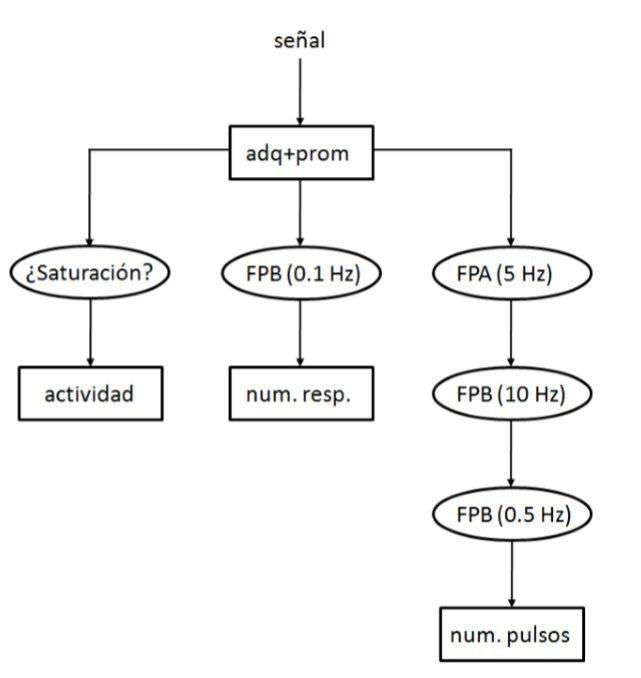

## Enlaces de interés

Raspberry:

- [Librería Scipy Signal](https://docs.scipy.org/doc/scipy/reference/signal.html) y [función sosfilter](https://docs.scipy.org/doc/scipy/reference/generated/scipy.signal.sosfilt.html#scipy.signal.sosfilt)

- [Librería Yodel](https://pypi.org/project/yodel/)

ESP32

## Estudio de filtros

% General
sample_rate = 200;

### Filtros para el ritmo cardíaco

**Filtro paso alta:**

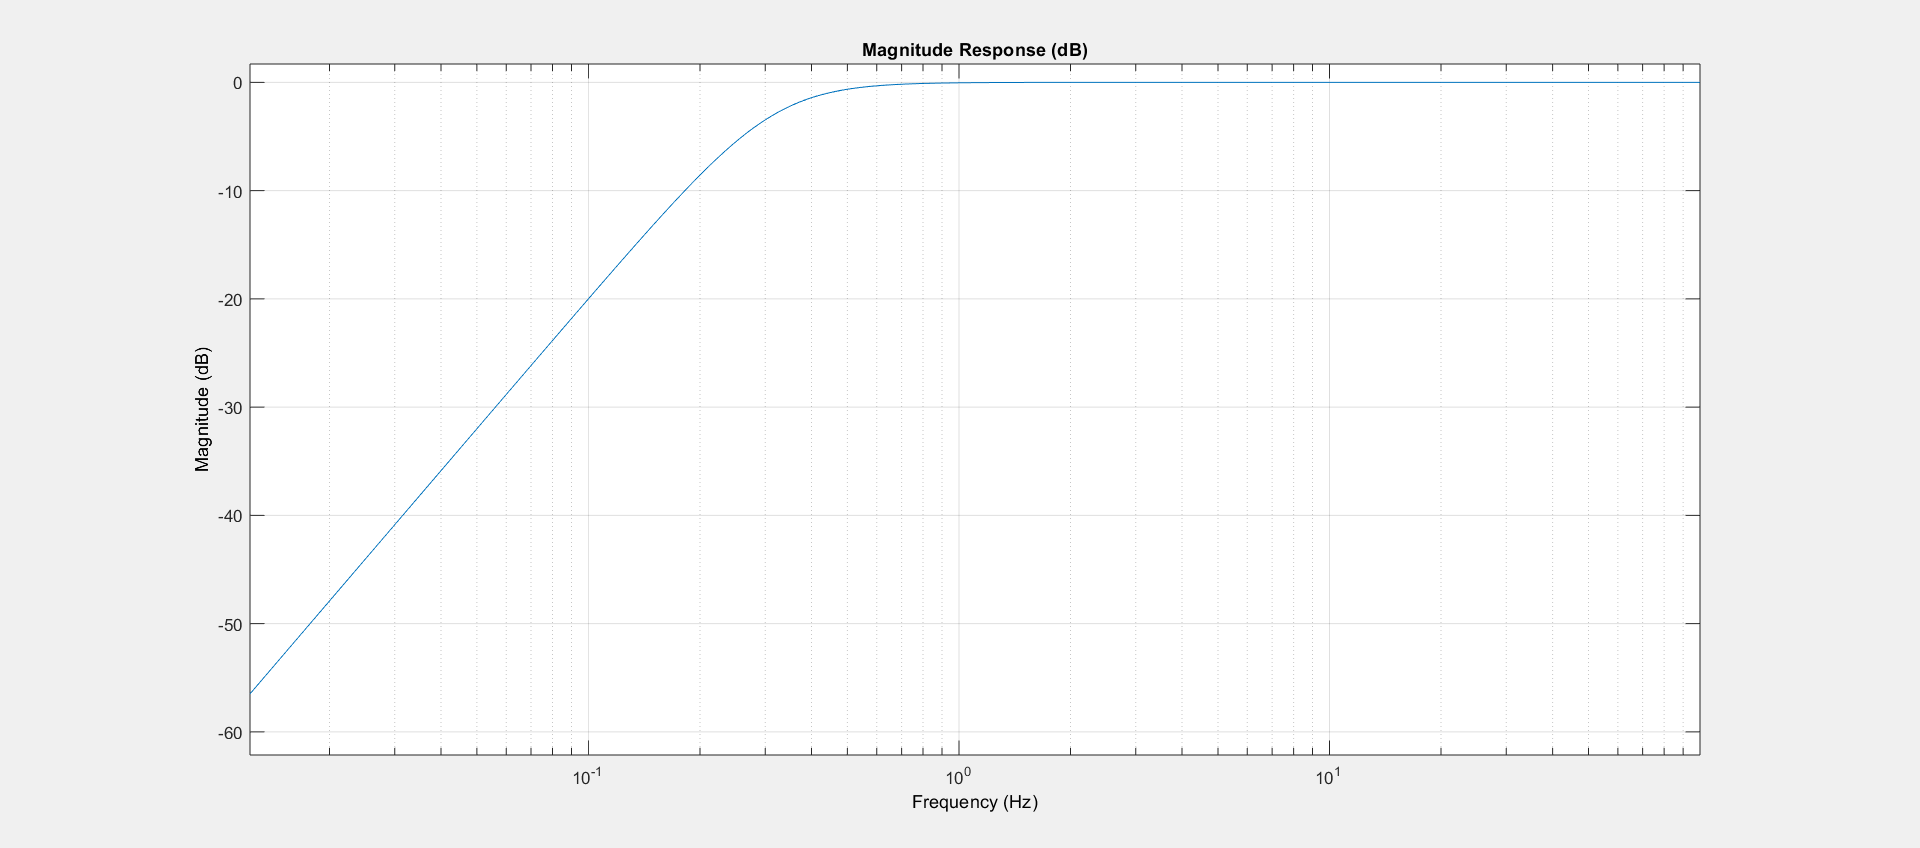

% Coeficientes paso alta
% Una sección biquad (orden 2)
% En total, pendiente de 40dB/dec
fL_h = 0.316;   % (FPA) Frecuencia de corte inferior

paso_alta_sos = [1, -2, 1,  1, -1.98598595723005, 0.986083473009604];
paso_alta_scale = 0.993017357559912;

biquad_hpf = dsp.BiquadFilter(paso_alta_sos,paso_alta_scale);
release(biquad_hpf)
figure(1)

h = fvtool(biquad_hpf,'Fs',sample_rate);
h.FrequencyScale = 'log';

**Filtro paso bajo:**

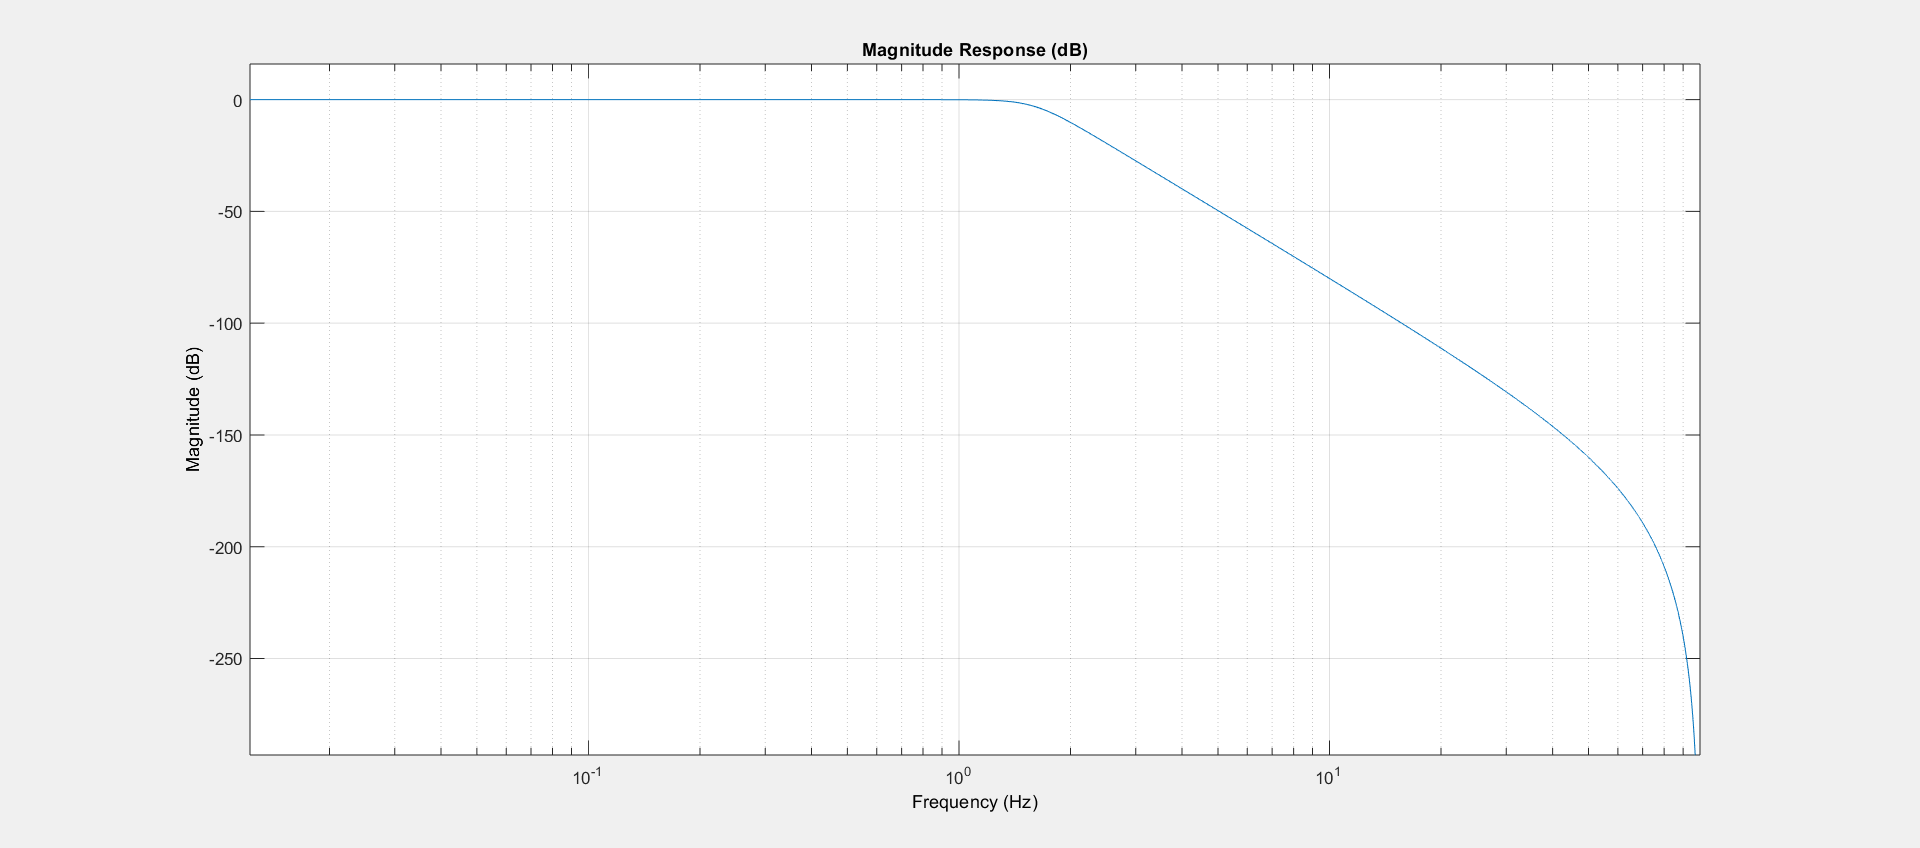

% Dos secciones biquad (orden 2) y una sección de primer orden
% En total, pendiente de 40dB + 40dB + 20dB = 100dB/dec(-)
fH_h = 1.597;   % (FPB) Frecuencia de corte superior

paso_baja_sos = [1, 2, 1,  1, -1.96698444058921, 0.969464886120290;
    1, 2, 1,  1, -1.91956461799301, 0.921985265243733;
    1, 1, 0,  1, -0.951024900504297,  0];
paso_baja_scale = [0.000620111382771082, 0.000605161812680899, 0.0244875497478514];
biquad_lpf = dsp.BiquadFilter(paso_baja_sos,paso_baja_scale);
figure(2)

g = fvtool(biquad_lpf,'Fs',sample_rate);
g.FrequencyScale = 'log';

**Filtro paso banda (total) (este no terminar de cuadrar con el PDF)**

% Coeficientes de los filtros juntos, como si fuesen más secciones
total_sos = [1, -2, 1,  1, -1.98598595723005, 0.986083473009604;
            1, 2, 1,  1, -1.96698444058921, 0.969464886120290;
            1, 2, 1,  1, -1.91956461799301, 0.921985265243733;
            1, 1, 0,  1, -0.951024900504297,  0];
total_scale = [0.993017357559912 0.000620111382771082, 0.000605161812680899, 0.0244875497478514];
biquad = dsp.BiquadFilter(total_sos,total_scale);
figure(3)
h = fvtool(biquad,'Fs',sample_rate);
h.FrequencyScale = 'log';
BW_h = fH_h - fL_h;

### Filtro para la respiración (este si coincide con PDF)

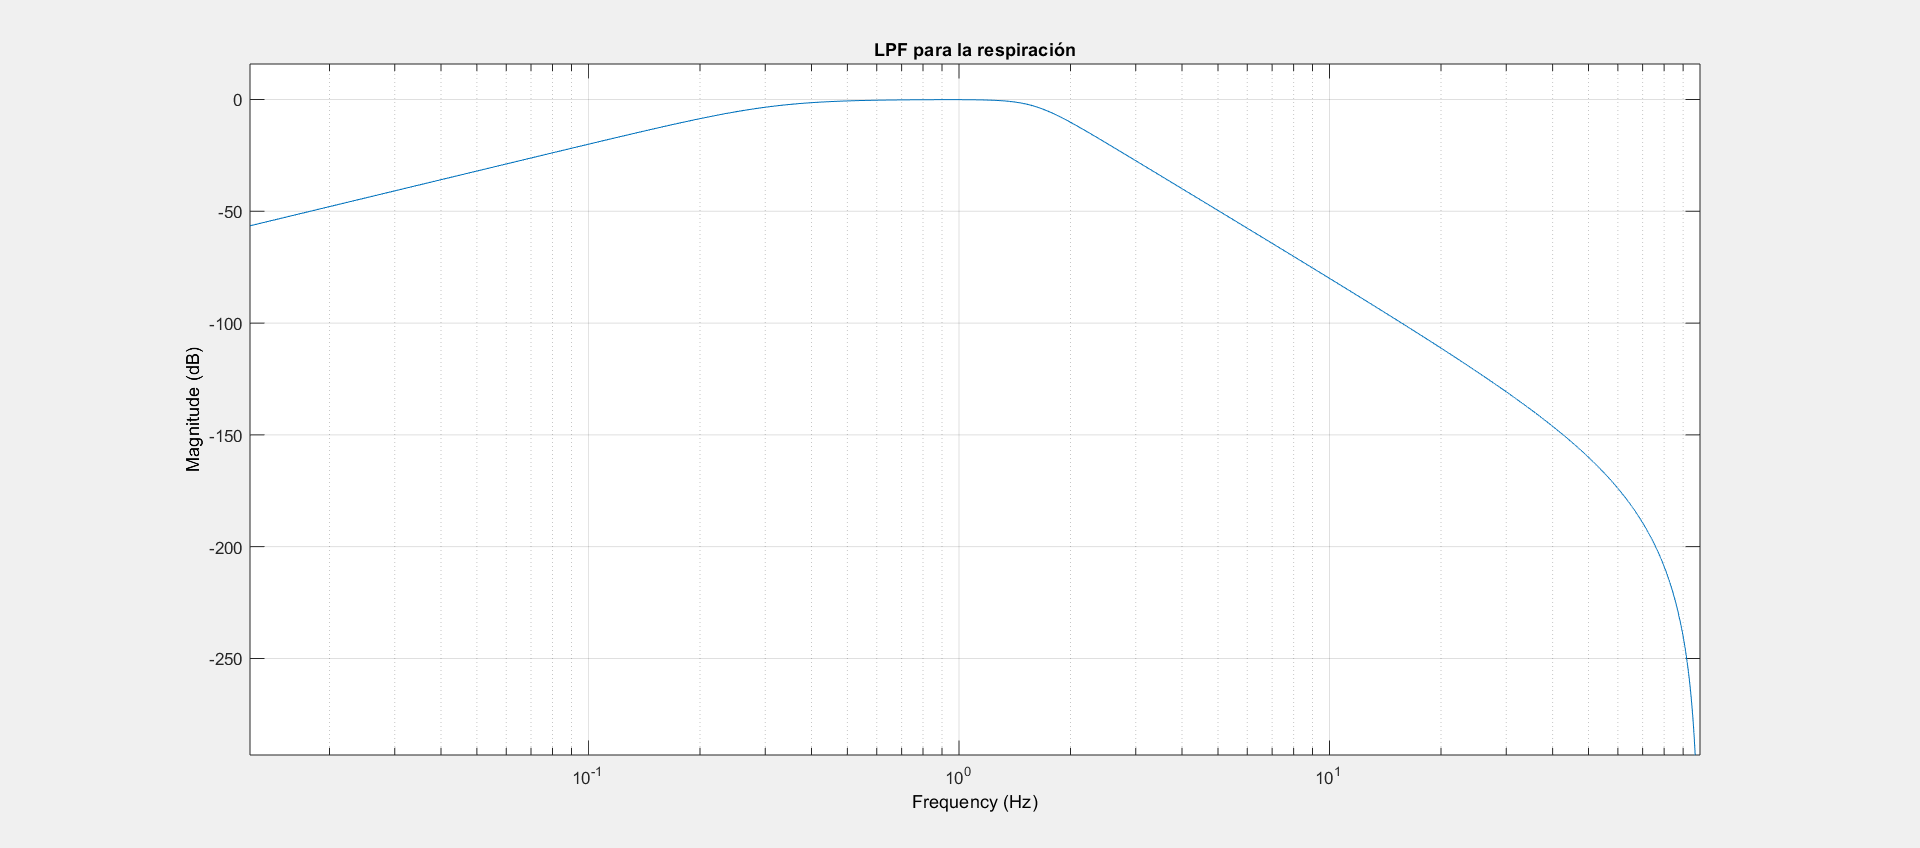

% Filtro paso baja. Una sección biquad y otra de primer orden
% En total, pendiente de -60dB/dec
fH_b = 0.22;
BW_b = fH_b;

resp_sos = [1, 2, 1,  1, -1.99305810207877, 0.993105797090774;
            1, 1, 0,  1, -0.993105714885021, 0];
resp_scale = [0.0000119237530005953, 0.00344714255748968];


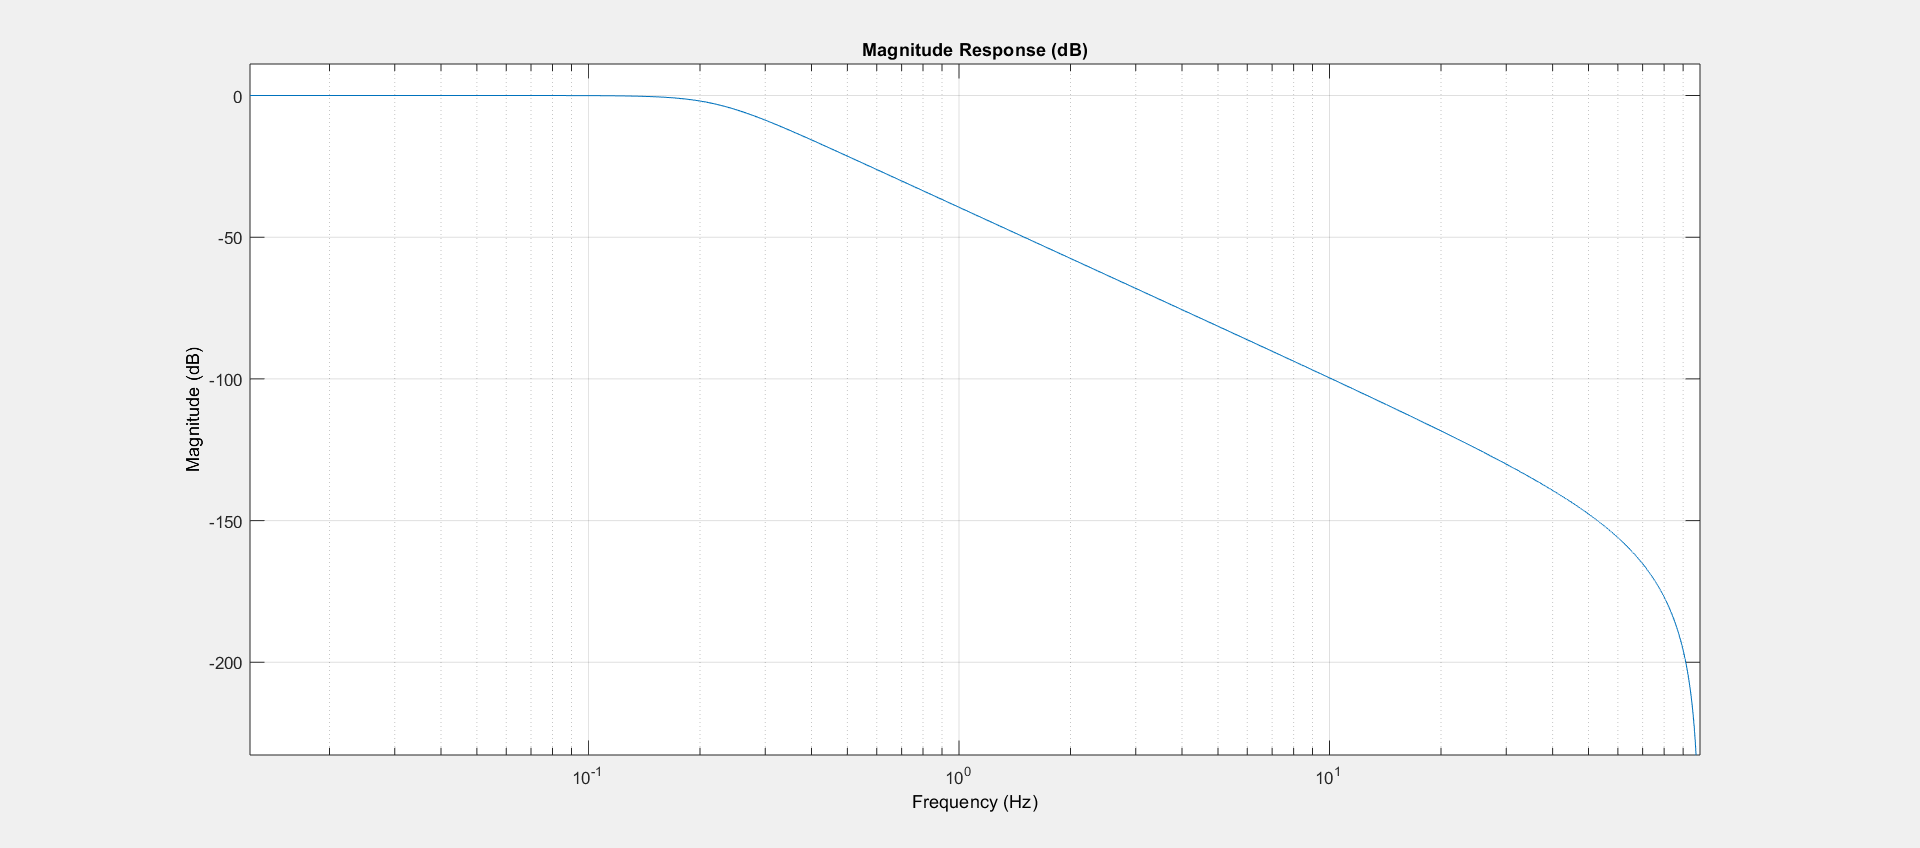

biquad_resp = dsp.BiquadFilter(resp_sos,resp_scale);
figure(4)

title('LPF para la respiración')
h = fvtool(biquad_resp,'Fs',sample_rate);
h.FrequencyScale = 'log';

### Análisis de señales de prueba

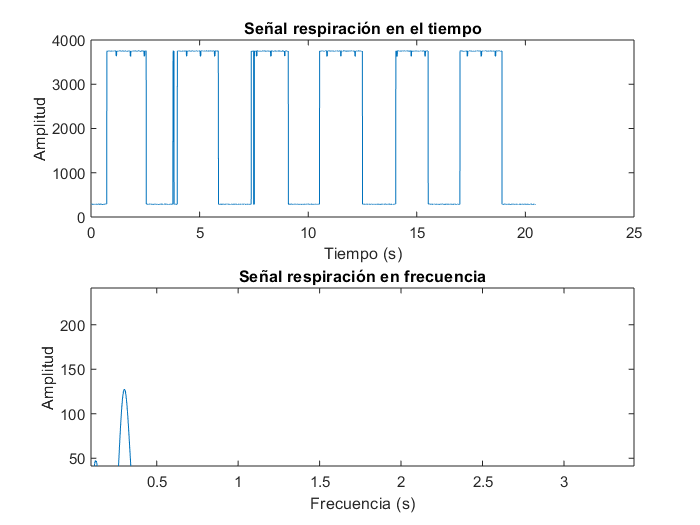

signal_b = round(csvread('signal_b.txt'));
signal_b = signal_b';
signal_h1 = readmatrix('signal_h1.txt');
signal_h1 = signal_h1(:,2);
signal_h2 = readmatrix('signal_h2.txt');

fs1 = 200;
fs2 = 500;


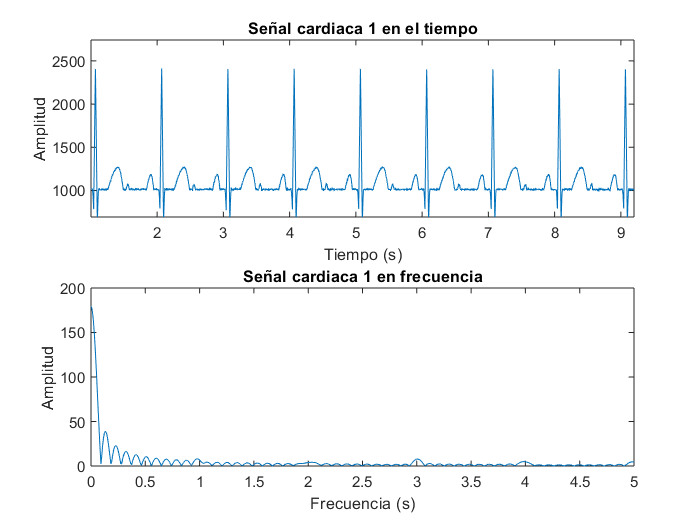

plot_signal(signal_b, fs1, ' respiración')

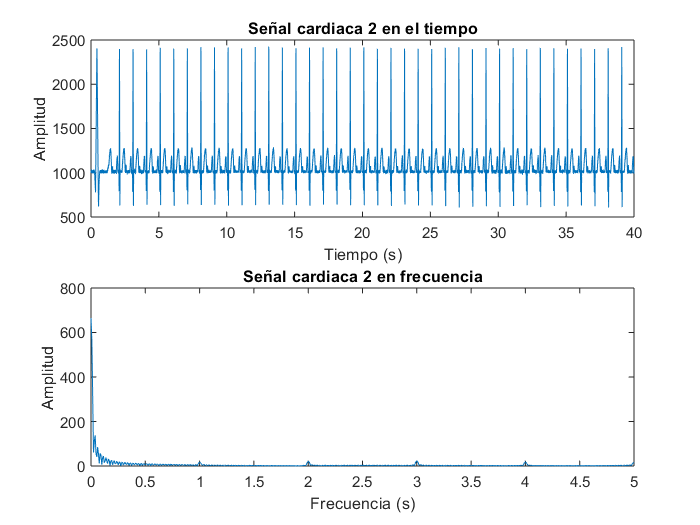

plot_signal(signal_h1, fs2, ' cardiaca 1')

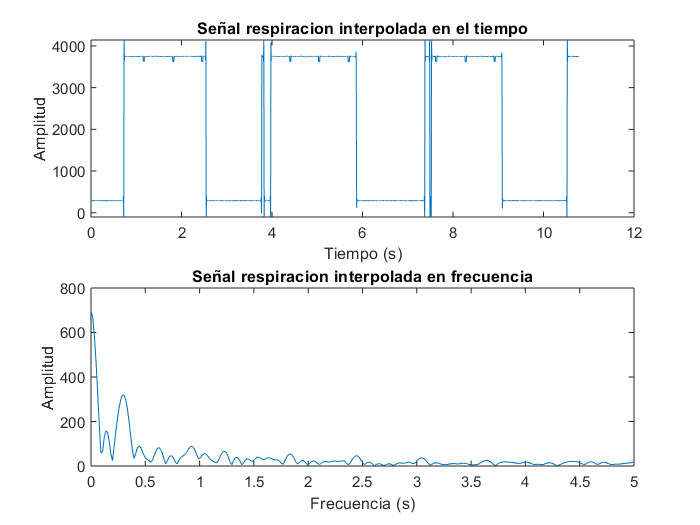

plot_signal(signal_h2, fs2, ' cardiaca 2')
% Interpolación para conseguir una fs de 1kHz
signal_bint = interp(signal_b, 5);
signal_h1int = interp(signal_h1, 2);
signal_bint = signal_bint(1:length(signal_h1int));  % Nos quedamos con la señal con el menor numero de muestras una vez interpoladas
sigmix = round(signal_bint + signal_h1int); % Suma de las señales cardiaca y respiratoria interpoladas con fs = 1000Hz


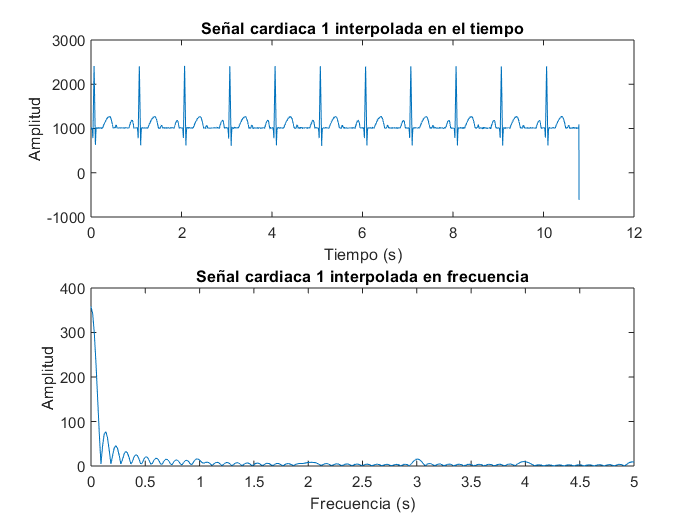

plot_signal(signal_bint, 1000, ' respiracion interpolada')

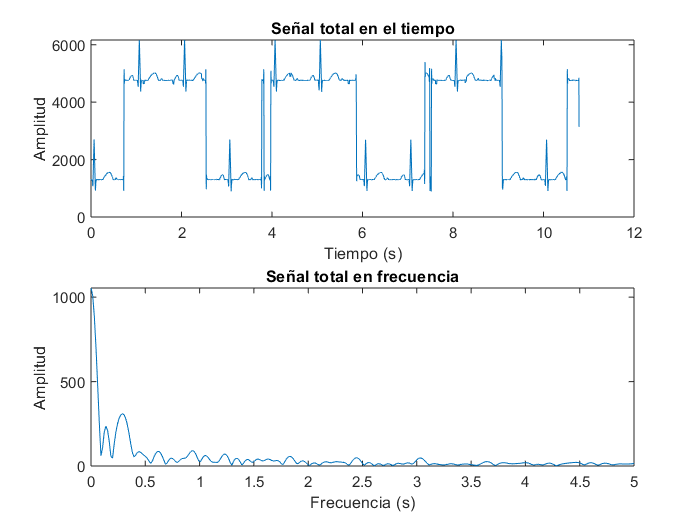

plot_signal(signal_h1int, 1000, ' cardiaca 1 interpolada')

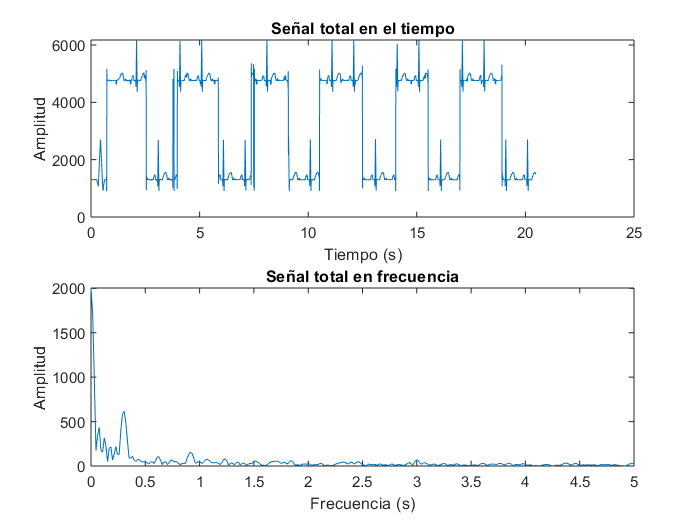

plot_signal(sigmix, 1000, ' total')
% Guardado de la señal suma
writematrix(sigmix, 'signal_bh1.txt')

% Interpolación para conseguir una fs de 1kHz (con la segunda señal cardiaca)
signal_bint = interp(signal_b, 5);
signal_h2int = interp(signal_h2, 2);
signal_h2int = signal_h2int(1:length(signal_bint));  % Nos quedamos con la señal con el menor numero de muestras una vez interpoladas
sigmix2 = round(signal_bint + signal_h2int); % Suma de las señales cardiaca y respiratoria interpoladas con fs = 1000Hz


plot_signal(sigmix2, 1000, ' total')
% Guardado de la señal suma
writematrix(sigmix2, 'signal_bh2.txt')

**Función para sobremuestrear las señales en un factor M (no se usa)**

function [signal_os] = oversample(signal, M)
    signal_os = zeros(M*length(signal),1);

    for i = 1:length(signal)
        signal_os((i-1)*M+1:i*M,1) = signal(i);
    end
end